Import fuzzy logic from fuzzy logic designer

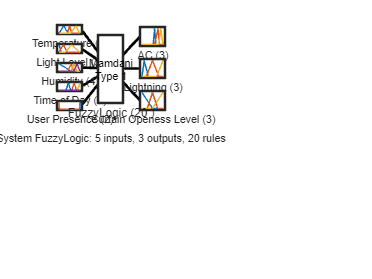

fis = readfis('FuzzyLogic.fis');
plotfis(fis);

Example plots of some inputs

plotmf(fis,"input",1)
plotmf(fis,"output",3)
gensurf(fis)

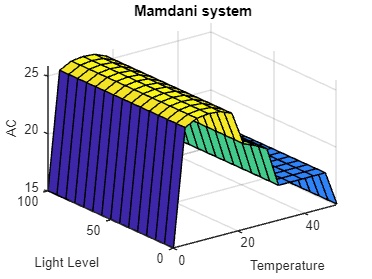

sug_fis = convertToSugeno(fis);
fis_struct = convertToStruct(fis);

gensurf(fis)
title('Mamdani system')

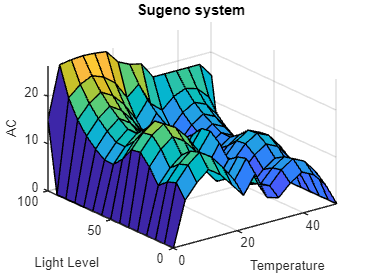

gensurf(sug_fis)
title('Sugeno system ')

% Extract membership functions and rules
input_mf = cell(1, 5);  % Cell array to store membership functions
for i = 1:5
    for j = 1:3
        prop = getfis(fis, 'input', i, 'mf', j);
        input_mf{i}{j} = prop;
    end
end

% Combine membership functions
x = 0:0.1:20;
mf = zeros(size(x));
for i = 1:5
    for j = 1:numel(input_mf{i})
        mf = max(mf, input_mf{i}{j}(x));
    end
end

% Plot combined membership function
figure('Tag', 'defuzz')
plot(x, mf, 'LineWidth', 3)
h_gca = gca;
h_gca.YTick = [0 .5 1];
ylim([-1 1])

Sample input to defuzzyfication and evaulation

% Define input values
sample_input = [50, 100, 70, 18, 1];

[output,fuzzifiedIn,ruleOut,aggregatedOut,ruleFiring] = evalfis(fis,sample_input);

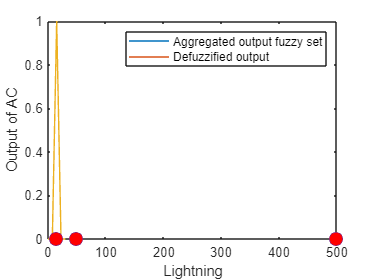


%Defuzzification of output 1
outputRange = linspace(fis.output(1).range(1),fis.output(1).range(2),length(aggregatedOut))'; 
% Plotting
figure;
plot(outputRange, aggregatedOut);
hold on;
plot(output, zeros(size(output)), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'red');
hold off;
xlabel(fis.Outputs(2).Name);
ylabel('Output of '+fis.Outputs(1).Name);
legend('Aggregated output fuzzy set', 'Defuzzified output');

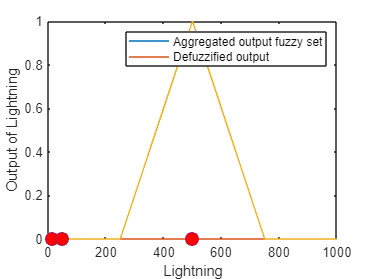


%Defuzzification of output 2
outputRange = linspace(fis.output(2).range(1),fis.output(2).range(2),length(aggregatedOut))'; 
% Plotting
figure;
plot(outputRange, aggregatedOut);
hold on;
plot(output, zeros(size(output)), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'red');
hold off;
xlabel(fis.Outputs(2).Name);
ylabel('Output of '+fis.Outputs(2).Name);
legend('Aggregated output fuzzy set', 'Defuzzified output');

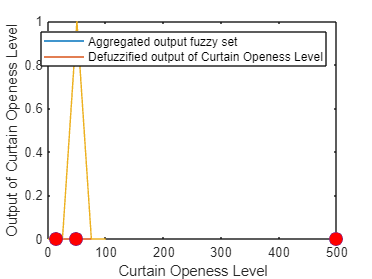



%Defuzzification of output 3
outputRange = linspace(fis.output(3).range(1),fis.output(3).range(2),length(aggregatedOut))'; 
% Plotting
figure;
plot(outputRange, aggregatedOut);
hold on;
plot(output, zeros(size(output)), 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'red');
hold off;
xlabel(fis.Outputs(3).Name);
ylabel('Output of '+fis.Outputs(3).Name);
legend('Aggregated output fuzzy set', 'Defuzzified output of '+ fis.Outputs(3).Name);